# **Sensor placement for quality monitoring**

**Load paths**

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## **Introduction**

Large-scale networks are difficult to monitor, and it is not possible to have sensors everywhere in the system, mainly due to costs. For this reason, we need to select the best locations to install sensors, in order to guarantee certain criteria, such as:

- Network coverage

- Detection delay

- Impact (e.g., number of people affected)

Sensor placement requires the following steps:

- Create simulation scenarios of contamination events

- Execute the simulation scenarios

- Measure the impact

- Formulate and solve an optimization problem

- If multiple objectives, costruct the Pareto front and select one solution

## Setup simulations for computing coverage matrix

rng(1)

%% Load EPANET Network and MSX
G = epanet('BWSN_Network_1.inp'); % Load EPANET Input file

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "BWSN_Network_1.inp"...
Input File "BWSN_Network_1.inp" loaded successfully.



%% Simulation Setup
t_d = 5 % days

t_d =      5


G.setTimeSimulationDuration(t_d*24*60*60); % Set simulation duration of 5 days

%% Get Network data
demand_pattern = G.getPattern;
roughness_coeff = G.getLinkRoughnessCoeff;
node_id = G.getNodeNameID;
Nnodes = G.getNodeCount;

### **Setup uncertainties**

%% Scenarios
Ns = 50; % Number of scenarios to simulate
u_p = 0.2 % pattern uncertainty

u_p =           0.2


u_r = 0.2 % roughness coefficient uncertainty

u_r =           0.2


Create the scenarios - first without contamination, to compute the bounds

max_inj_conc = 10.0

max_inj_conc =     10


inj_start_time = 1 % 

inj_start_time =      1


inj_duration = 24 % maximum duration of 12 hours

inj_duration =     24


% Injection location, magnitude, start time, duration 
inj_sc=[randi(G.NodeCount,Ns,1), max_inj_conc*ones(Ns,1), (inj_start_time)*ones(Ns,1), inj_duration*ones(Ns,1)] 

inj_sc =     54    10     1    24
    93    10     1    24
     1    10     1    24
    40    10     1    24
    19    10     1    24
    12    10     1    24
    25    10     1    24
    45    10     1    24
    52    10     1    24
    70    10     1    24


### **Create the coverage matrix**

The coverage matrix is a binary matrix, where earh row is a scenario, and each column is a node. If a certain contamination scenario affects (can reach) a certain node, the flag is true, else false.

K = zeros(1,Nnodes);
for i = 1:Ns
    disp(['Iteration ', int2str(i)])
    
    % Randomize demands
    r_p = -u_p + 2*u_p.*rand(size(demand_pattern,1),size(demand_pattern,2));
    new_demand_pattern = demand_pattern + demand_pattern.*r_p;
    G.setPatternMatrix(new_demand_pattern); % Set new patterns
    
    % Randomize pipe roughness
    r_r = -u_r + 2*u_r.*rand(size(roughness_coeff,1),size(roughness_coeff,2));
    new_roughness_coeff = roughness_coeff + roughness_coeff.*r_r;
    G.setLinkRoughnessCoeff(new_roughness_coeff); % Set new roughness coefficients
    
    c = zeros(1,Nnodes);
    c(inj_sc(i,1)) = inj_sc(i,2);
    G.setNodeInitialQuality(c);
    
    qsp = G.getComputedTimeSeries.NodeQuality;
    K(i,:) = max(qsp)>0;
end

Iteration 1
Iteration 2
Iteration 3
Iteration 4
Iteration 5
Iteration 6
Iteration 7
Iteration 8
Iteration 9
Iteration 10
Iteration 11
Iteration 12
Iteration 13
Iteration 14
Iteration 15
Iteration 16
Iteration 17
Iteration 18
Iteration 19
Iteration 20
Iteration 21
Iteration 22
Iteration 23
Iteration 24
Iteration 25
Iteration 26
Iteration 27
Iteration 28
Iteration 29
Iteration 30
Iteration 31
Iteration 32
Iteration 33
Iteration 34
Iteration 35
Iteration 36
Iteration 37
Iteration 38
Iteration 39
Iteration 40
Iteration 41
Iteration 42
Iteration 43
Iteration 44
Iteration 45
Iteration 46
Iteration 47
Iteration 48
Iteration 49
Iteration 50


## **Optimization problem**

- Avoid having sensors to monitor the same area

- Some scenarios affect all nodes, and some others, may not affect any node.

This means: select those columns that have ones, so that there is at least one positive flag '1' in as many rows as possible

- $Y$ is the vector of "scenario observability" (number of scenarios $\times$ 1)

- $u$ is the solution, a binary vector (number of nodes $\times$ 1)

- $K$ is the coverage matrix (number of scenarios $\times$ number of nodes)


$$Y = Ku$$


The optimization problem is formed (in its simplest form) as


$$\arg\max f(u)$$



$$u\in\{0,1\}^{N}}$$



$$\sum u_i = m$$


Where $f(u)$ is the objective function.  The simplest function is "the percentage of scenarios which can be 'detected' by the sensors".

We can have multiple functions, and in that case, we need multi-objective optimization.

### Solving for a single solution

% random selection of nodes
rng(1)
Nsensors = 5 % number of sensors

Nsensors =      5


total_combinations = nchoosek(Nnodes, Nsensors) % 275 Millions for 5 sensors in 129 nodes

total_combinations = int32
   275234400



% Create a random solution
s = randperm(Nnodes, Nsensors) % return random

s =     54    93     1    39    19


% solution
u = zeros(Nnodes, 1);
u(s) = 1;
% compute output
Y = K*u

Y =      5
     1
     1
     4
     1
     0
     5
     5
     5
     0


% how many non-zero elemenets in Y?
perc_coverage = sum(Y>0)/double(Ns)*100

perc_coverage =     48


### **Larger scenario dataset**

- How many scenarios should we create?

- In general, the more scenarios, the more robust your solution

- Simulate contamination events at different time steps

- Simulate different hydraulic conditions

**Load results from BWSN 2006 competition (37K scenarios)**

% Table of all scenarios vs nodes, with flag = 1 
% if the contaminant is observed at that node 
load Kall.mat 
[Nsall, ~] = size(Kall)

Nsall =        37152


**Repeat solution computation for the larger dataset**

rng(1)
Nsensors = 5 % number of sensors

Nsensors =      5



% Create a random solution
s = randperm(Nnodes, Nsensors) % return random

s =     54    93     1    39    19


% solution 
u = zeros(Nnodes, 1);
u(s) = 1;
% compute output
Y = Kall*u;
% how many non-zero elemenets in Y?
perc_coverage = sum(Y>0)/double(Nsall)*100

perc_coverage =        36.609


### **Randomized solutions for multiple sensors**

How many sensors to install? Let's create a lot of random solutions

rng(1)
epochs = 1000

epochs =         1000


maxsensors = 20

maxsensors =     20


fx = [];
for i = 1:epochs
    ns = randi(maxsensors);
    s = randperm(Nnodes, ns);
    u = zeros(Nnodes, 1);
    u(s) = 1;
    Y = Kall*u;
    fx(i,:) = [ns, sum(Y>0)/double(Nsall)*100];
end

Plotting the results

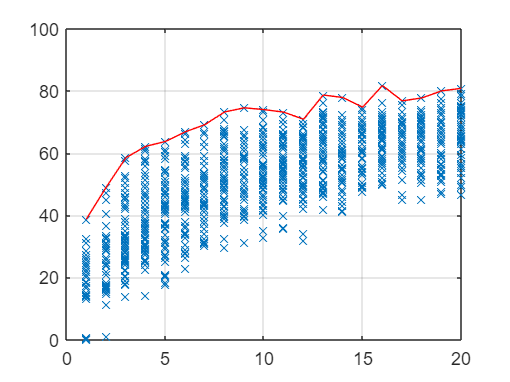

figure
plot(fx(:,1), fx(:,2),'x')
grid on
hold all
maxfx=[];
for i = 1:maxsensors
    maxfx(i,:)= [i max(fx(fx(:,1)==i,2))];
end
plot(maxfx(:,1), maxfx(:,2),'r-')

**Question:*** Is this a valid way of solving problems?*

## **Solving the optimization problem**

- Integer/Mixed Integer Quadradic Programming

- Evolutionary Optimization (Single-objective)

- Evolutionary Optimization (Multi-objective)

### Genetic algorithms

rng(2)
Nsensors = 5

Nsensors =      5


[Nsall, Nnodes] = size(Kall)

Nsall =        37152


Nnodes =    129


gafunc = @(x) calc_score(x,Kall,Nsall)

gafunc = function_handle with value:
    @(x)calc_score(x,Kall,Nsall)


[x,fval] = ga(gafunc, Nsensors,[],[],[],[],ones(Nsensors,1),Nnodes*ones(Nsensors,1));

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


sensors = round(x)

sensors =     46   125    84   101    15


sensorsID = G.getNodeNameID(sensors)

sensorsID = 1×5 cell array
    {'JUNCTION-45'}    {'JUNCTION-126'}    {'JUNCTION-83'}    {'JUNCTION-100'}    {'JUNCTION-14'}


score = -fval

score =        81.769


Plot the location of the sensors

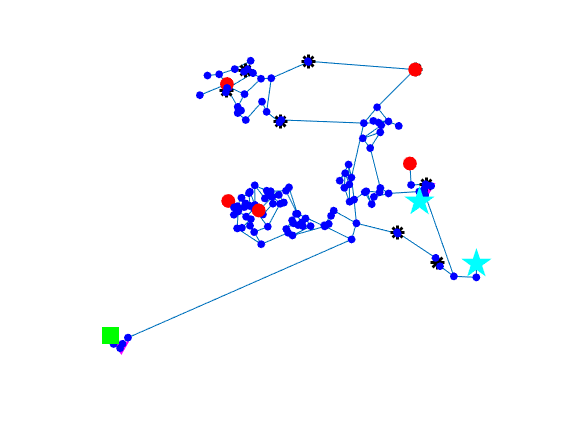

ans =   Axes with properties:

             XLim: [-2566.7 28488]
             YLim: [-1354.5 14899]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


figure
G.plot('highlightnode',sensorsID)

Compare with Krause et al. 2008

figure
krause2008sensorsID = {'JUNCTION-17', 'JUNCTION-83', 'JUNCTION-122', 'JUNCTION-31', 'JUNCTION-45'};
score = -calc_score(G.getNodeIndex(krause2008sensorsID), Kall, Nsall)

score =        75.571


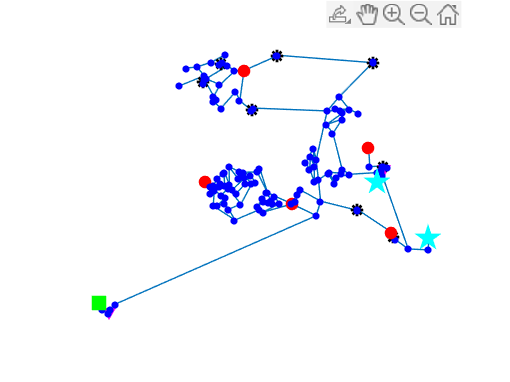

ans =   Axes with properties:

             XLim: [-2566.7 28488]
             YLim: [-1354.5 14899]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


G.plot('highlightnode',krause2008sensorsID)

### **Multiple objectives**

- Minimize detection time and maximize coverage

- No single optimal solution

- Need to compute a pareto front of solutions

% Table of all scenarios vs nodes, with flag = 1 
% if the contaminant is observed at that node 
load Kall.mat 
% Table of all scenarios vs nodes, detection time in minutes
load Tall.mat

**Solve the multi-objective optimization using the NSGA-II method**

rng(12)
Nsensors = 5

Nsensors =      5


[Nsall, Nnodes] = size(Kall)

Nsall =        37152


Nnodes =    129


gamultifunc = @(x) calc_score_multi(x,Kall,Nsall,Tall)

gamultifunc = function_handle with value:
    @(x)calc_score_multi(x,Kall,Nsall,Tall)


[x,fval] = gamultiobj(gamultifunc, Nsensors,[],[],[],[],ones(Nsensors,1),Nnodes*ones(Nsensors,1))

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


x =        34.048       65.621       121.85       83.943       18.394
       34.048       65.621       121.85       83.941       18.394
       34.134        65.57       121.84       83.941       18.397
       34.048       65.621       121.85       83.943       18.394
       34.048       65.621       121.85       83.941       18.394
       34.048       65.621       121.85       83.942       18.394
       12.673       47.176       116.99       83.869        16.37
       12.673       47.177       116.99       83.869        16.37
       34.048       65.621       121.85       83.943       18.394
       34.114       65.581       121.85       83.942       18.395


fval =       -72.545          780
      -72.545          780
      -72.545          780
      -72.545          780
      -72.545          780
      -72.545          780
      -77.894         1055
      -77.894         1055
      -72.545          780
      -72.545          780


sensors = round(x)

sensors =     34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    34    66   122    84    18
    13    47   117    84    16
    13    47   117    84    16
    34    66   122    84    18
    34    66   122    84    18


**Plot the results and the Pareto Front**

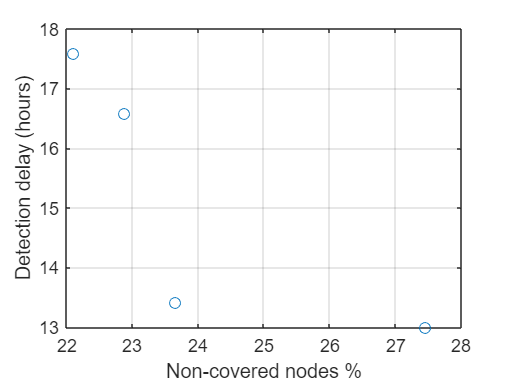

figure
plot(100+fval(:,1),fval(:,2)/60,'o')
grid on
xlabel('Non-covered nodes %')
ylabel('Detection delay (hours)')

### **Function definitions**

Single objective function

function gafunc = calc_score(x, Kall, Nsall)
    gafunc = -sum(max(Kall(:,round(x)),[],2))/Nsall*100;
end

Multi-objective function

function gamultifunc = calc_score_multi(x, Kall, Nsall,Tall)
    gamultifunc(1) = -sum(max(Kall(:,round(x)),[],2))/Nsall*100;
    gamultifunc(2) = median(min(Tall(:,round(x)),[],2));
end